Get model Unified Model of GFMI

close all
clear all
clc

main_dir=''; % set this to your parent directory-whereever you have this file
MatPower_path=''; %Directry where you have Matpower installed

cd(main_dir)
addpath(genpath(MatPower_path));

run("Parameters.m")
load("Unified_VSG.mat");
GFMI_1 = Unified_GFMI;

load("Parameters.mat")

# Benchmark GFMI

load("Parameters.mat")

mpc = SMIB_PowerFlow(rg,lg);  
% Optionally, insert code here to modify mpc fields based on Rg and Lg.

% Run the power flow for this operating point
PowerFlow_results = runpf(mpc);


MATPOWER Version 8.0, 17-May-2024
Power Flow -- AC-polar-power formulation

Newton's method converged in 4 iterations.
PF successful

Converged in 0.74 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              2     Total Gen Capacity     999.0        -999.0 to 999.0
Generators         1     On-line Capacity       999.0        -999.0 to 999.0
Committed Gens     1     Generation (actual)     -0.8               0.0
Loads              1     Load                    -0.9              -0.1
  Fixed            1       Fixed                 -0.9              -0.1
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0


% Extract bus 1 angle (in degrees) and voltage magnitude (p.u)
Angle = PowerFlow_results.bus(1,9);
Voltage_mag = PowerFlow_results.bus(1,8);

% Calculate space phasors
Angle_rad = deg2rad(Angle);
Vc_phasor = Voltage_mag * V_LL/sqrt(3) * exp(1j * Angle_rad); % line-to-neutral voltage
Vg_phasor = V_LL/sqrt(3);

% Compute impedance values (assuming these parameters are constant)
Zt = (rf2 + rg + 1j * 2*pi*50 * (lf2 + lg));
Z2 = rf2 + 1j * 2*pi*50 * lf2;

% Calculate current and PCC voltage phasors
I2_phasor = (Vc_phasor - Vg_phasor) / Zt;
Vpcc_phasor = (Vc_phasor - I2_phasor * Z2) * sqrt(2);

% Store operating point values
delta0 = Angle_rad;    
Vpcc_D0 = real(Vpcc_phasor);
Vpcc_Q0 = imag(Vpcc_phasor);

% Transform Vc phasor into d–q components
Vc_dq0 = Vc_phasor * exp(-1j * Angle_rad) * sqrt(2);
Vc_d0 = real(Vc_dq0);
Vc_q0 = imag(Vc_dq0);

% Transform I2 phasor into d–q components
I2_dq0 = I2_phasor * exp(-1j * Angle_rad) * sqrt(2);
i2_d0 = real(I2_dq0);
i2_q0 = imag(I2_dq0);

%Make model for each variation
A_Benchmark = double(subs(GFMI_1.sym_A));
Benchmark_Poles=eig(A_Benchmark);

Range=linspace(500,2000,40);
SweepVariable="h";
VariableLabel="h";
A_Stage1 = cell(1, length(Range));
for i = 1:length(Range)
    A_Stage1{i} = subs(GFMI_1.sym_A, 'h', Range(i));
end

We compute the power flow and the linear operating point for each variation of grid impedance. 

We then build models for the different variations and store it in a structured file that we will later use to substitute the rest of the static parameters.

We substitute the rest of the static grid parameters

load("Parameters.mat")

for i = 1:length(Range)
    A_Stage2{i}=double(subs(A_Stage1{1,i}));
end


# Generate Figures

load("Parameters.mat")

mpc = SMIB_PowerFlow(rg,lg);  
% Optionally, insert code here to modify mpc fields based on Rg and Lg.

% Run the power flow for this operating point
PowerFlow_results = runpf(mpc);


MATPOWER Version 8.0, 17-May-2024
Power Flow -- AC-polar-power formulation

Newton's method converged in 4 iterations.
PF successful

Converged in 0.36 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              2     Total Gen Capacity     999.0        -999.0 to 999.0
Generators         1     On-line Capacity       999.0        -999.0 to 999.0
Committed Gens     1     Generation (actual)     -0.8               0.0
Loads              1     Load                    -0.9              -0.1
  Fixed            1       Fixed                 -0.9              -0.1
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0


% Extract bus 1 angle (in degrees) and voltage magnitude (p.u)
Angle(i) = PowerFlow_results.bus(1,9);
Voltage_mag(i) = PowerFlow_results.bus(1,8);

% Calculate space phasors
Angle_rad = deg2rad(Angle(i));
Vc_phasor = Voltage_mag(i) * V_LL/sqrt(3) * exp(1j * Angle_rad); % line-to-neutral voltage
Vg_phasor = V_LL/sqrt(3);

% Compute impedance values (assuming these parameters are constant)
Zt = (rf2 + rg + 1j * 2*pi*50 * (lf2 + lg));
Z2 = rf2 + 1j * 2*pi*50 * lf2;

% Calculate current and PCC voltage phasors
I2_phasor = (Vc_phasor - Vg_phasor) / Zt;
Vpcc_phasor = (Vc_phasor - I2_phasor * Z2) * sqrt(2);

% Store operating point values
delta0 = Angle_rad;    
Vpcc_D0 = real(Vpcc_phasor);
Vpcc_Q0 = imag(Vpcc_phasor);

% Transform Vc phasor into d–q components
Vc_dq0 = Vc_phasor * exp(-1j * Angle_rad) * sqrt(2);
Vc_d0 = real(Vc_dq0);
Vc_q0 = imag(Vc_dq0);

% Transform I2 phasor into d–q components
I2_dq0 = I2_phasor * exp(-1j * Angle_rad) * sqrt(2);
i2_d0 = real(I2_dq0);
i2_q0 = imag(I2_dq0);

%Make model for each variation
A_Benchmark = double(subs(GFMI_1.sym_A));
Benchmark_Poles=eig(A_Benchmark);

# Generate Figures

## Main figure settings

% Create figure for plots
scale = 2;
Figure_width  = 7.98;   % Saved width (cm)
Figure_height = 4.2;    % Saved height (cm)
Main_Figure_pos = scale * [0, 0, Figure_width, Figure_height];
color_palet = colormap(turbo(length(Range))); % Generate the color palette

% Create figure with default LaTeX interpreter and formatted properties
Main_Figure = figure('Units', 'centimeters', ...
                     'Position', Main_Figure_pos, ...
                     'PaperUnits', 'centimeters', ...
                     'PaperPosition', Main_Figure_pos, ...
                     'PaperSize', Main_Figure_pos(3:4), ...
                     'PaperPositionMode', 'manual', ...
                     'Resize', 'off', ...
                     'DefaultTextInterpreter', 'latex', ...
                     'DefaultAxesFontSize', 14, ...
                     'DefaultAxesFontName', 'Times New Roman', ...
                     'DefaultAxesTickLabelInterpreter', 'latex', ...
                     'DefaultLegendInterpreter', 'latex', ...
                     'DefaultTextFontSize', 14, ...
                     'DefaultTextFontName', 'Times New Roman', ...
                     'DefaultAxesBox', 'on');


Pole_axes_pos = scale * [1, 0.75, Figure_width*0.5, Figure_height*0.75];
Pole_axes = axes('Units', 'centimeters', 'Position', Pole_axes_pos);
hold(Pole_axes, 'on');
for i = 1:length(Range)
    Poles = eig(A_Stage2{i});
    plot(Pole_axes, real(Poles), imag(Poles), 'x', 'MarkerSize', 4, 'LineWidth', 1, 'Color', color_palet(i, :));
end

% Plot the benchmark poles with labels
for k = 1:length(Benchmark_Poles)
    text(Pole_axes,real(Benchmark_Poles(k)), imag(Benchmark_Poles(k)),sprintf('$$\\lambda_{%d}$$', k),'Color', 'black'); % Add lambda number as text
end

xline(Pole_axes, 0, 'k--', 'LineWidth', 1);
axis(Pole_axes, [-700, 50, -300, 300]);
set(Pole_axes, 'XGrid', 'on', 'YGrid', 'on', 'GridLineStyle', '--', 'GridColor', 'k');
xlabel(Pole_axes, '$$\sigma$$', 'FontWeight', 'bold', 'Interpreter', 'latex', 'VerticalAlignment', 'top','HorizontalAlignment', 'center');
ylabel(Pole_axes, '$$j \omega$$', 'FontWeight', 'bold', 'Interpreter', 'latex', 'VerticalAlignment', 'baseline','HorizontalAlignment', 'center');


## Color settings

colormap(turbo(length(Range)));
clim([min(Range), max(Range)]); % Set the color axis range
cb = colorbar(Pole_axes);
cb.Location="northoutside"

cb =   ColorBar with properties:

    Location: 'northoutside'
      Limits: [500 2000]
    FontSize: 11.2500
    Position: [0.1260 0.7432 0.4992 0.0530]
       Units: 'normalized'

  Show all properties


cb.Ticks = [linspace(min(Range), max(Range), 4)];
cb.TickLabels=round(cb.Ticks,2); 
cb.Label.String = '$$h_\mathrm{v}$$ (W.s$$^2$$/rad)';cb.Label.Interpreter = 'latex';
cb.Label.VerticalAlignment='baseline';

## Zoomed 1 figure settings

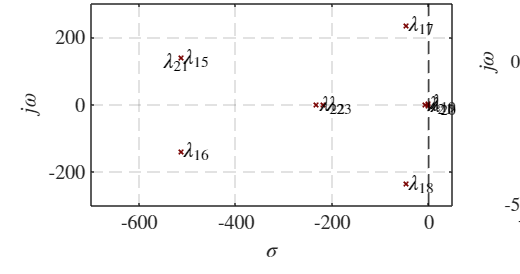

Error using matlab.graphics.internal.name (line 112)
Unable to create output file '\\ad.monash.edu\home\User098\sali0043\Desktop\PhD\MyResearchPublications\Paper_SSMComparison\V4_05_03_25\Eigenvalue Analysis\Results_Unedited\VSG_h_EA.svg', No such file or directory.

Error in print (line 7

Zoom1_axes_pos = scale * [5.8, 0.75, Figure_width*0.25, Figure_height*0.75];
Zoom1_axes = axes('Units', 'centimeters', 'Position', Zoom1_axes_pos);
hold(Zoom1_axes, 'on');
for i = 1:length(Range)
    Poles = eig(A_Stage2{i});
    plot(Zoom1_axes, real(Poles), imag(Poles), 'x', 'MarkerSize', 4, 'LineWidth', 1, 'Color', color_palet(i, :));
end

% Plot the benchmark poles with labels
for k = 1:length(Benchmark_Poles)
    text(Zoom1_axes,real(Benchmark_Poles(k)), imag(Benchmark_Poles(k)),sprintf('$$\\lambda_{%d}$$', k),'Color', 'black'); % Add lambda number as text
end
% add_damping_ratio_lines(4);
xline(Zoom1_axes, 0, 'k--', 'LineWidth', 1);
axis(Zoom1_axes, [-2, 0.5, -5, 5]);
set(Zoom1_axes, 'XGrid', 'on', 'YGrid', 'on', 'GridLineStyle', '--', 'GridColor', 'k');
xlabel(Zoom1_axes, '$$\sigma$$', 'FontWeight', 'bold', 'Interpreter', 'latex', 'VerticalAlignment', 'top','HorizontalAlignment', 'center');
ylabel(Zoom1_axes, '$$j \omega$$', 'FontWeight', 'bold', 'Interpreter', 'latex', 'VerticalAlignment', 'baseline','HorizontalAlignment', 'center');

## Damping Ratio fcn

function add_damping_ratio_lines(text_radius)
    angle_degrees = [-45, 45];  % Angles for damping ratio lines

    max_radius = max(abs([xlim, ylim]));  % Use the maximum absolute value of axis limits

    hold on;

    for i = 1:length(angle_degrees)
        angle = angle_degrees(i);
        zeta = cosd(angle);  % Damping ratio (cosine of the angle)

        A = cosd(angle);  % Real axis component
        O = sind(angle);  % Imaginary axis component

        % Generate the damping line
        x = linspace(0, -max_radius * A, 100);  % Negative real axis
        y = linspace(0, max_radius * O, 100);  % Positive imaginary axis

        plot(x, y, 'LineWidth', 1, 'LineStyle', ':', 'Color', 'k');  % Dashed black line

        % Add damping ratio text if text_radius is not zero
        if text_radius ~= 0
            x_text = -A * text_radius;
            y_text = O * text_radius;

            text(x_text, y_text, sprintf('$$\\zeta$$ = %3.2f', zeta),  'Color', 'k','HorizontalAlignment', 'right');
        end
    end
end